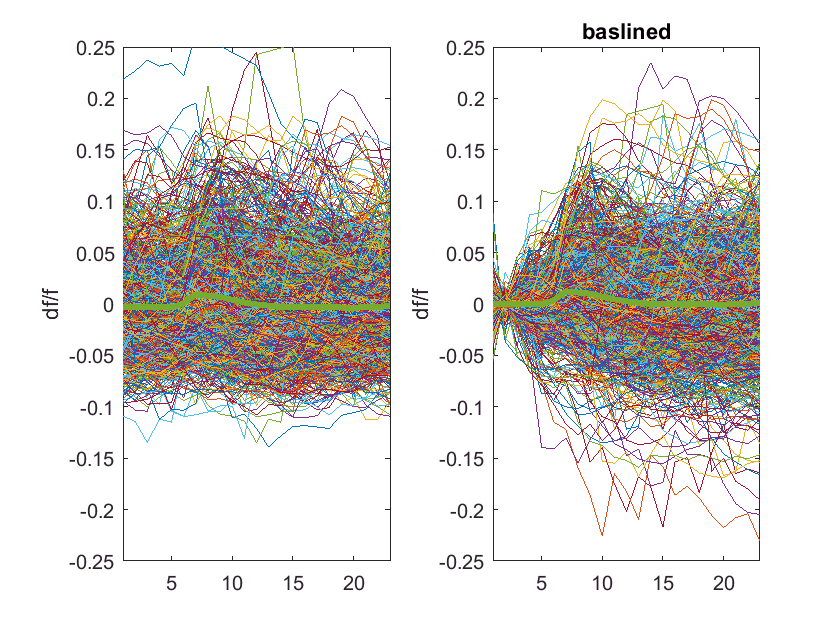

% V1, PRE & POST BASEline

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames

figure % make one figure for all subplots

for j = 1:2 % pre & post baseline figs

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot
    
        clear onePtAllFramesAndTrials % new var each point
        clear recomboOnePtAllFramesAllTrialMinusMeanBase
        clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
        % collect all trials over all frames for the ith point
        onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
        onePtAllFramesAndTrials = onePtAllFramesAndTrials';
        
         if j == 1 % if making pre-baselined fig
                
           % pre baseline fig
           subplot(1,2,j)
                
           clear x_axis
           x_axis = 1:size(onePtAllFramesAndTrials,2); % length of frames
           % plot one baseline corrected trace at a time
           %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase) % plot dfof the first point vs frames for each trial   
           % hold on because we're doing it for every trial on the same plot
           plot(x_axis,onePtAllFramesAndTrials)
               
           hold on
           % get mean baselined trace across all trials
           meanOnePtAllFramesAndTrials = mean(onePtAllFramesAndTrials,1); % mean across trials
           % plot mean non-baselined
           plot(x_axis,meanOnePtAllFramesAndTrials,'linewidth',3)
            
           ylim([-0.25 0.25]) 
           xlim([1 length(x_axis)])
           ylabel('df/f')
    
           ax = gca;
           x.XTick = [1:1:length(x_axis)];
                
       end 
       
       if j == 2; % if making baseline fig
            
       % for every trace, subtract the baseline value at that point from each frame value
  
           clear tr % for each trial in onePtAllFramesAndTrial
           for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
              % getting TRIAL VECTOR
              clear onePtAllFramesOneTrial % make new var for each trial
              % index into each trace/vector & save as variable
              onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
        
              % getting MEAN BASEline VALUE for each TRIAL
              clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
              % collect 4 baseline frames for tr-th ith trial
              allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
              clear mean4baseFramesOnePtOneTrial
              % get mean value of baseline values for ith point
              mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
        
              % BASEline CORRECTion of TRIAL VECTOR
        
              % new baseline-corrected trace for each trial
              % calulate the baselined trace for the ith trial
              onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
              % collect CORRECTed TRIAL VECTORS in matrix
              % save each tr-th baselined trace in a matrix for plotting mean later
              % (only clear this outside the loop for each point)
              recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
             % PLOT
             subplot(1,2,j) % post baseline fig
             clear x_axis
             x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
             % plot one baseline corrected trace at a time
             %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase) % plot dfof the first point vs frames for each trial   
             % hold on because we're doing it for every trial on the same plot
             plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                
             hold on % hold for next trial
                
         end % end tr loop
        
      % outside of trial loop but inside j 'if'
      
      hold on % hold for plotting mean over subplot
        
      % get mean baselined trace across all trials
      meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
   
      plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
      title('baslined')
        
      ylim([-0.25 0.25]) 
      xlim([1 length(x_axis)])
      ylabel('df/f')

      ax = gca;
      x.XTick = [1:1:length(x_axis)];
                
       end % end 2nd if statement
       
    end % end i loop
    
end % end j loop

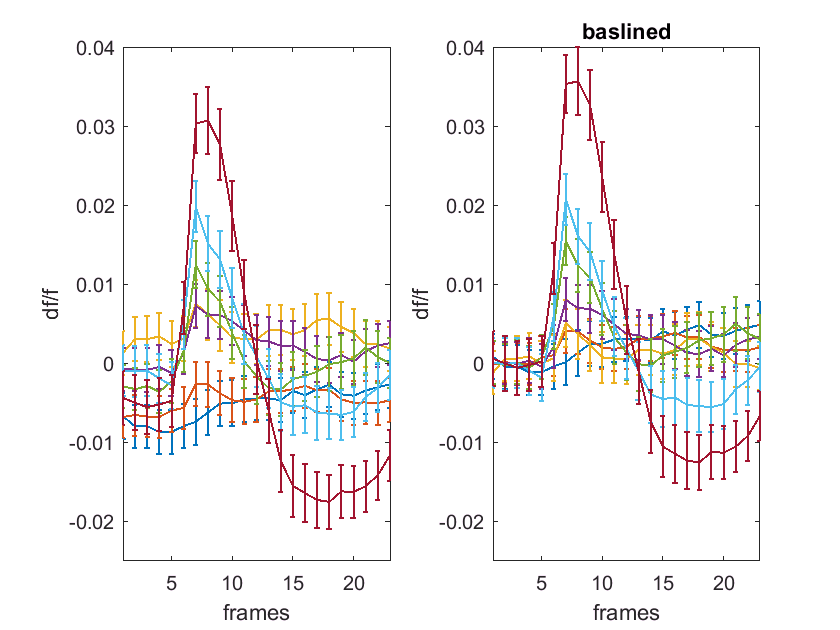

% V1, PRE & POST BASEline

% MEAN across TRIALS for each CONTRAST

figure % make one figure for all subplots

for j = 1:2 % pre & post baseline figs
    
    clear recomboOnePtAllFramesAllTrialMinusMeanBase

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot
        if j == 1 % if making pre-baselined fig
            
            clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
                % MEAN over trials
                meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
                % 1x51 variable that has dfof of one point averaged across trials
                % at the c-th contrast, for all frames
            
                %STDEV
                err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                % stdOverTrialsPTSdfof = (std(meanOverTrialsPTSdfof)/sqrt(trials);
                % err = stdOverTrialsPTSdfof*ones(size(meanOverTrialsPTSdfof)); % b/c just one stdev for whole trace across trials at the c-th contrast
            
                % for later group analysis - for each contrast, a trace for the i-th point
                % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
                % PLOT
                clear x_axis
                x_axis = 1:length(meanOverTrialsPTSdfof);
                subplot(1,2,j)
                errorbar(x_axis,meanOverTrialsPTSdfof,err,'linewidth',1)
                ylim([-0.025 0.04]) 
                xlim([1 length(x_axis)])
                %st = title(sprintf('%s', reigonsTitle{r}));
                ylabel('df/f')
                xlabel ('frames')
        
                hold on % all contrast traces on one fig
                
            end % end c loop
       
        end % end 1st j if
           
        if j == 2; % if making baseline fig
           
           subplot(1,2,j)
           
           clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
                % MEAN over trials
                clear meanOverTrialsPTSdfof
                meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
                % 1x # trials variable that has dfof of one point averaged across trials
                % at the c-th contrast, for all frame
                
                % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
                % trials and we already took the mean across trials
                clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
                % collect 4 baseline frames 
                allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
                clear mean4baseFramesOnePtOneCon
                % get mean value of baseline values for ith point
                mean4baseFramesOnePtOneCon = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
                % BASEline CORRECTION
                % new baseline-corrected trace for each mean trace
                clear onePtOneConMinusMeanBase
                onePtOneConMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneCon;
        
                % COLLECT corrected traces in matrix
                % (only clear this each tine go thru j loop (new one each subplot)
                recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneConMinusMeanBase;
            
                %STDEV of deviation from the mean oover trials
                clear err
                % our mean trace is averaged over trials. We want to know how much the trials 
                % values varied, not how much the mean trial values vary over time...
                err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                
                % for later group analysis - for each contrast, a trace for the i-th point
                % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
                % PLOT
                clear x_axis
                x_axis = 1:length(onePtOneConMinusMeanBase);
                subplot(1,2,j)
                errorbar(x_axis,onePtOneConMinusMeanBase,err,'linewidth',1)
                ylim([-0.025 0.04]) 
                xlim([1 length(x_axis)])
                title('baslined')
                % st = title(sprintf('%s', reigonsTitle{r}));
                ylabel('df/f')
                xlabel ('frames')
        
                hold on % all contrast traces on one fig
                
            end % end c loop
                
       end % end 2nd j if
       
    end % end i loop
    
end % end j loop

% V1, PRE & POST BASEline

% CRF

% get PEAK FRAMES
clear f
for f = 1:3 % average over 3 peak frames
   peakFrameIdx(i) = stimOnsetFrame+i+1 % always skip the onset frame and the one after, then take the
   % next 3 frames
end % now you can index the peak frames automatically if you change stim onset

peakFrameIdx =      7    10    11


peakFrameIdx =      7    10    11


peakFrameIdx =      7    10    11


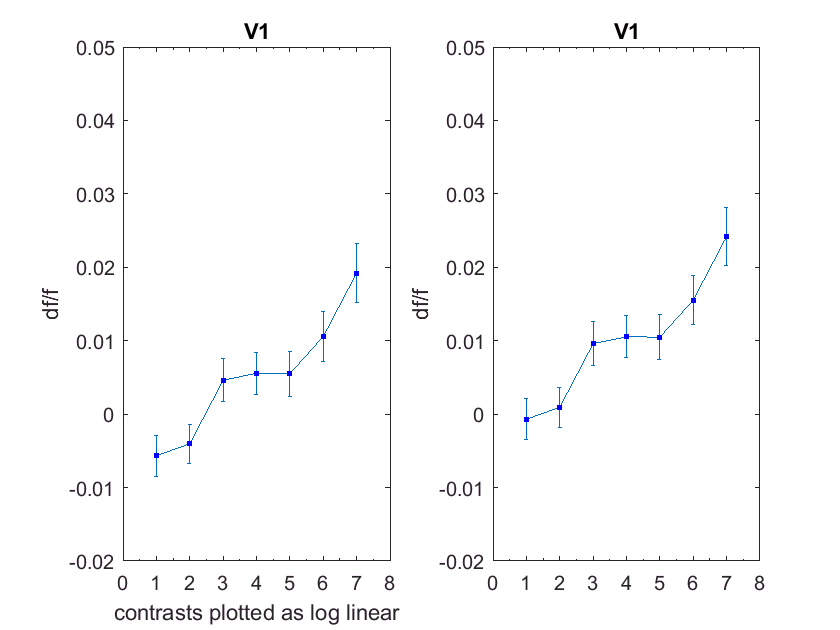


figure % make one figure for all subplots

for j = 1:2 % pre & post baseline figs
    
    clear clear contStdErr

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot
        if j == 1 % if making pre-baselined fig
            
            clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
                % CRF POINTS for each contrast, i-th point
                % use a range of frames (reduce noise):
        
                % take the i-th points over the frame range, for the c-th trials
                % returns 3 (frames) by # trials
                sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
        
                % take the mean over frames
                %returns 1 x # trials
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
                % now I need the mean over trials to get one df/f value representing the
                % average fluorescence over 3 frames and over the c-th trials for the i-th point
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
                % now I want to collect each c-th CRF value for this point
                % creates 1 x 7 (contrasts)
                contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
                % STDERR
                % now I want to calulate the StdErr for each CRF point calulated above
                % (one err value for each contrast)
                % that means I want the error over trials, not over frames
                % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
                contStdErr(1,c) = stdErr; % clear outside j loop
        
            end % end contrast loop - have full CRF for ith point
 
            % PLOTTING
            % one figure, one subplot for each point, each subplot has CRF for that poin
            % size subplot based on 7 contrasts
            subplot(1,2,j)
            % 7 contrasts for x axis
            x_axis = [1 2 3 4 5 6 7];
            crfChart = errorbar(x_axis,contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,contStdErr,'-s','MarkerSize',3,...
            'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
            st = title(sprintf('%s', reigons{i}));
            ylim([-0.02 0.05]) 
            xlim([0, 8])
            ylabel('df/f')
            xlabel('contrasts plotted as log linear')
    
            ax=crfChart.Parent;
            ax.XMinorTick = 'on'; %more tick marks
            set(ax, 'XTick', 0:1:8);
                
        end % end 1st if statemet
             
        if j == 2; % if making baseline fig
               
            clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
                cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
                % CRF POINTS for each contrast, i-th point
                % use a range of frames (reduce noise):
        
                % take the i-th points over the frame range, for the c-th trials
                % returns 3 (frames) by # trials
                clear sq5FramesOverTrialsPTSdfof
                sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
        
                % take the mean over frames
                %returns 1 x # trials
                clear meanOverFramesSq5FramesOverTrialsPTSdfof
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
                % now I need the mean over trials to get one df/f value representing the
                % average fluorescence over 3 frames and over the c-th trials for the i-th point
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
                % now I want to collect each c-th CRF value for this point
                % creates 1 x 7 (contrasts)
                contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
                % GET mean BASEline
                % the baseline for each CRF value is the mean of the baseline frames for ith point
                % get all frames & cth trials
                ithPtCthTrialsAllFrames = squeeze((PTSdfof(i,:,cthTrials)));
                baselineFramesIthPtCthTrials = ithPtCthTrialsAllFrames(baselineIdx,:); % baselineIdx defined elsewhere
                % now have baseline frames x all trials
                % take mean across trials 
                meanBaselineFramesIthPtCthTrials = mean(baselineFramesIthPtCthTrials,2);
                %meanBaselineFramesIthPtCthTrials = squeeze(baselineFramesIthPtCthTrials);
                % take mean across frames
                meanBaselineFramesIthPtCthTrials = mean(meanBaselineFramesIthPtCthTrials,1);
            
                % do BASEline CORRECTION
                % subtract the cth baseline from the flourescence at each c
                clear CRFminusMeanBase
                CRFminusMeanBase = contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof-meanBaselineFramesIthPtCthTrials;

                % STDERR
                % now I want to calulate the StdErr for each CRF point calulated above
                % (one err value for each contrast)
                % that means I want the error over trials, not over frames
                % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
                contStdErr(1,c) = stdErr; % clear outside j loop
        
            end % end contrast loop - have full baselined CRF for ith point
            
            % inside 2nd j loop still
 
            % PLOTTING
            % one figure, one subplot for each point, each subplot has CRF for that poin
            % size subplot based on 7 contrasts
            subplot(1,2,j)
            % 7 contrasts for x axis
            x_axis = [1 2 3 4 5 6 7];
            crfChart = errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
            'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
            st = title(sprintf('%s', reigons{i}));
            ylim([-0.02 0.05]) 
            xlim([0, 8])
            ylabel('df/f')
            %xlabel('contrasts plotted as log linear')
            title('baselined')
    
            ax=crfChart.Parent;
            ax.XMinorTick = 'on'; %more tick marks
            set(ax, 'XTick', 0:1:8);
                
        end % end 2nd j if statement
            
    end % end i loop
    
end % end j loop

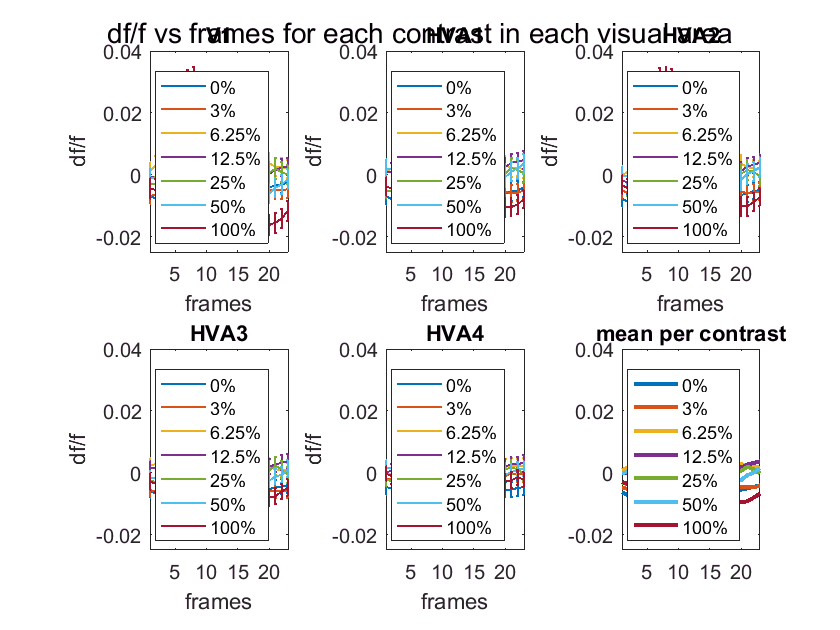

sst =   Text (mean per contrast) with properties:

                 String: 'mean per contrast'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [12 0.040889 1.4211e-14]
                  Units: 'data'

  Show all properties


% CRF w/ PEAK (MEAN @ LATENCY) --> determined by looking at latency.. just taking mean at these frames, not using max function
% CRF over frames 14-16

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 14:16;


subplotNum = 1;
r = 1;

figure 
suptitle('Contrast Response Functions for Each Point')
for i = 1:length(xpts)
    
    clear sq5FramesOverTrialsPTSdfof
    clear meanOverFramesSq5FramesOverTrialsPTSdfof
    clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contStdErr
    
    for c = 1:length(uniqueContrasts)
        
        clear cthTrials
        cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthConOrderedByTrialMeetCriteria == uniqueContrasts(c);  
        
        % CRF POINTS for each contrast, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthTrials));
        
        % take the mean over frames
        %returns 1 x 76 (trials)
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each c-th CRF value for this point
        % creates 1 x 7 (contrasts)
        contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
        contStdErr(1,c) = stdErr;
        
    end 
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1 2 3 4 5 6 7];
    crfChart = errorbar(x_axis,contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    st = title(sprintf('%s', reigons{r}));
    ylim([-0.02 0.05]) 
    xlim([0, 8])
    ylabel('df/f')
    xlabel('contrasts plotted as log linear')
    
    ax=crfChart.Parent;
    ax.XMinorTick = 'on'; %more tick marks
    set(ax, 'XTick', 0:1:8);
%     clear xt
%     xt={'0' ; '0.03' ; '0.0625' ; '0.125' ; '0.25'; '0.5'; '1';} ; 
%     set(gca,'xtick',1:7);
%     set(gca,'xticklabel',xt);
    
subplotNum = subplotNum+1;
r = r+1;
    
end 
    